s = [1 1 2 3];
t = [2 4 3 4];
weights = [1 1 1 1];
G = graph(s,t,weights);
%plot(G)


x = double(dec2bin(0:15)=='1');
[i,j] = findedge(G);
allFval = sum(x(:,i) .* (1-x(:,j)),2) + sum(x(:,j) .* (1-x(:,i)),2);
allSols = array2table([x,allFval],VariableNames=["x1","x2","x3","x4","f"]);
allSols = sortrows(allSols,"f","descend")

allSols = 16×5 table
    x1    x2    x3    x4    f
    __    __    __    __    _

    0     1     0     1     4
    1     0     1     0     4
    0     0     0     1     2
    0     0     1     0     2
    0     0     1     1     2
    0     1     0     0     2
    0     1     1     0     2
    0     1     1     1     2
    1     0     0     0     2
    1     0     0     1     2
    1     0     1     1     2
    1     1     0     0     2
    1     1     0     1     2
    1     1     1     0     2
    0     0     0     0     0
    1     1     1     1     0


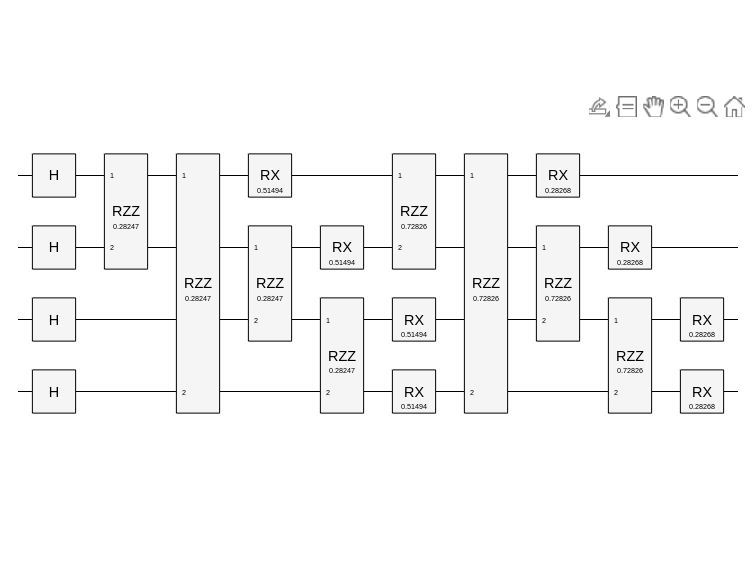


%%%------------- qubo----------------

%qprob = maxcut2qubo(G);
%result = solve(qprob,Algorithm=qaoa)

%result.BestFunctionValue

%result.BestX

%%%-------------------------------------


gamma = 1;
beta = 3;
theta = rand(2,numLayers);
circuit = qaoaCircuit(G,theta,2);

figure;
plot(circuit);

drawnow; % Forces immediate rendering


numLayers = 2; % Equal to j ()
numShots = 1000;
objFcn = @(theta) -expectedObjectiveValue(theta,G,numLayers,numShots);
bound = repmat(pi,2*numLayers,1);
%bound is a column vector of 2*numLayers elements with pi in each element
x0Theta = rand(2,numLayers);
options = optimoptions("surrogateopt",InitialPoints=x0Theta,MaxFunctionEvaluations=100);
[angles,bestfval] = surrogateopt(objFcn,-bound,bound,[],[],[],[],[],options)

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


angles =    -1.9578    2.6456    0.9698    2.5563


bestfval = -3.9680



optimizedCircuit = qaoaCircuit(G,angles,numLayers);
sv = simulate(optimizedCircuit)

sv =   QuantumState with properties:

    BasisStates: [16×1 string]
     Amplitudes: [16×1 double]
      NumQubits: 4


histogram(sv)




%reg = "us-east-1";
%bucketPath = "s3://amazon-braket-mathworks/doc-examples";
%device = quantum.backend.QuantumDeviceAWS("Aria 1",S3Path=bucketPath,Region=reg)


%task = run(optimizedCircuit,device,NumShots=1000);
%wait(task)

%results = fetchOutput(task);
%histogram(results)